load('D:\Monkey_Data\monkey64chan-10062019-001_formatted.mat')

trial_i=10;
figure(1);
subplot(1,2,1)
title("RASTER")
imagesc(permute(rasters(28,:,trial_i:trial_i+50),[1,3,2]));colorbar()

Error using image
Color data must be an m-by-n-by-3 or m-by-n matrix.

Error in imagesc (line 52)
    hh = image(varargin{:}, 'CDataMapping', 'scaled');

subplot(1,2,2)
title("LFP")
imagesc(permute(lfps(28,:,trial_i:trial_i+50),[1,3,2]));colorbar()

[Sort_Name, sort_idx] = SortCell(Trials.imageName, 1)% Trials.imageName

Sort_Name = 7051×1 cell array
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                             }
    {'[01]UFH_123'                     

sort_idx =     13
   129
   169
   246
   292
   378
   445
   527
   611
   684


rasters = permute(rasters,[3,2,1]);
lfps = permute(lfps,[3,2,1]);

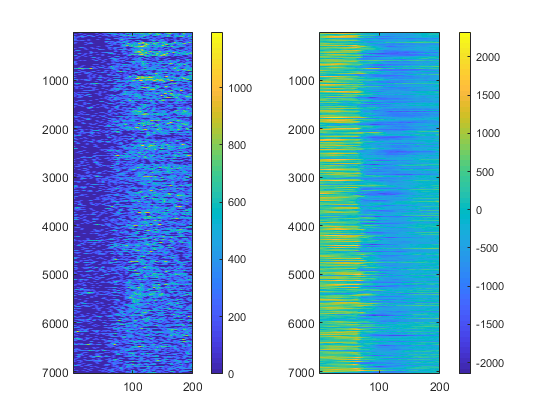

channel_j = 28
figure(3);
subplot(1,2,1)
title("RASTER")
imagesc(rasters(sort_idx, :, channel_j));colorbar()
subplot(1,2,2)
title("LFP")
imagesc(lfps(sort_idx, :, channel_j));colorbar()

gen_num_i = zeros([length(Sort_Name),1])

gen_num_i =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


block_i = 0;
natural_stim_i = zeros([length(Sort_Name),1]);
stim_i = 1;
for i = 1:length(Sort_Name)
    if ~contains(Sort_Name{i}, "block")
        while ~contains(Sort_Name{i}, sprintf("[%02d]", stim_i))
            stim_i = stim_i + 1;
        end
        natural_stim_i(i) = stim_i;
        gen_num_i(i) = -1;
    else
        while ~contains(Sort_Name{i}, sprintf("block%03d", block_i))
            block_i = block_i + 1;
        end
        gen_num_i(i) = block_i;
    end
end

### The PSTH of natural stimuli 

nat_stim_fr = zeros(max(natural_stim_i), size(rasters, 2), size(rasters, 3));
nat_stim_fr_std = zeros(max(natural_stim_i), size(rasters, 2), size(rasters, 3));
for i = 1:max(natural_stim_i)
    nat_stim_fr(i,:,:) =    mean(rasters(sort_idx(natural_stim_i==i), :, :),1);
    nat_stim_fr_std(i,:,:) = std(rasters(sort_idx(natural_stim_i==i), :, :),1,1);
end

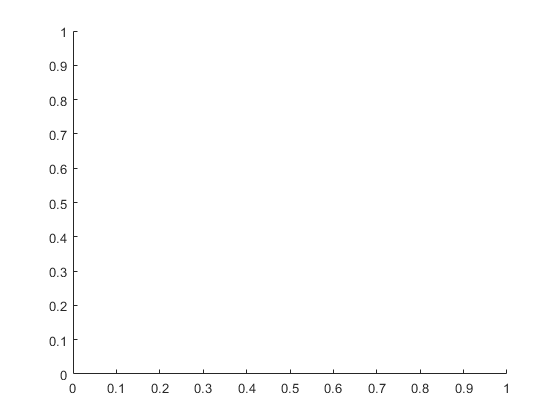

channel_j = 28;
figure;clf;hold on;

for i = 1:max(natural_stim_i)
    % errorbar(nat_stim_fr(i,:,channel_j),nat_stim_fr_std(i,:,channel_j))
    plot(nat_stim_fr(i,:,channel_j))
end

Error using plot
Data cannot have more than 2 dimensions.

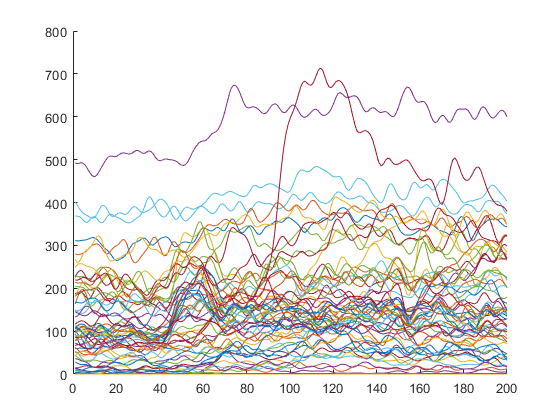

figure;clf;hold on;
for channel_j = 1:size(rasters, 3)
    % errorbar(nat_stim_fr(i,:,channel_j),nat_stim_fr_std(i,:,channel_j))
    plot(nat_stim_fr(i,:,channel_j))
end

imagesc

trial_i=2;
eye_pos = Trials.eyeXY{trial_i};
figure(2);clf;hold on
plot(eye_pos(:,1), eye_pos(:,2))
Break_Fix = single(sum(eye_pos.^2, 2) > 1)
scatter(eye_pos(:,1), eye_pos(:,2), 5, 1+Break_Fix)
axis equal 
% xlim(Trials.XY{trial_i}(1) + [- 0.5, 0.5] * Trials.width{trial_i}(1))
% ylim(Trials.XY{trial_i}(2) + [- 0.5, 0.5] * Trials.width{trial_i}(1))